# 2.7 - Newton's Method

## CP1c

For verifying exercises 3 through 6.

### The system

F = @(x) [x(1)^2  - 4*x(2)^2 - 4;
         (x(1)-1)^2 + x(2)^2 - 4];
DF = @(x) [2*x(1)  , -8*x(2);
           2*x(1)-2,  2*x(2)];

### Two steps of Newton

newton([1; 1], F, DF, 0.5e-8, 2)

ans =     5.8479
    1.6778


### Decent estimate

newton([1; 1], F, DF, 0.5e-8, 2)

ans =     5.8479
    1.6778


Turns out this system converges rather swiftly.

## CP3

**Two** solutions for the system $u^3 - v^3 + u = 0$ and $u^2 + v^2 = 1$ - the last equation is the unit circle.

### Defining the system:

F = @(x) [x(1)^3 - x(2)^3 + x(1);
          x(1)^2 + x(2)^2 - 1];
DF = @(x) [3*x(1)^2 + 1,  -3*x(2)^2;
           2*x(1)      ,   2*x(2) ];

### Applying Newton's method:

newton([1; 1], F, DF, 0.5e-8, 10)

ans = "Done after 6 iterations"

ans =     0.5080
    0.8614


newton([-2; -2], F, DF, 0.5e-8, 10)

ans = "Done after 7 iterations"

ans =    -0.5080
   -0.8614


## CP5a

Spheres with radius 1 and centers (1,1,0), (1,0,1), and (0,1,1).

**Two **points in common.

Checking them out with GeoGebra:

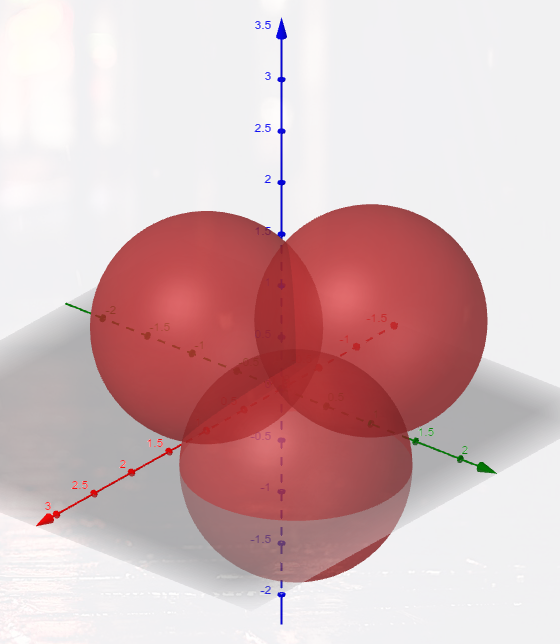

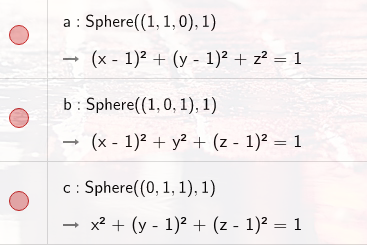

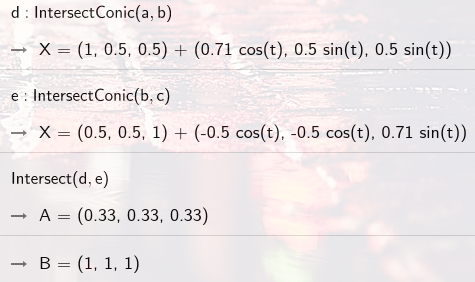

### Defining the matrix functions:

F = @(x) [(x(1) - 1)^2 + (x(2) - 1)^2 +  x(3)^2      - 1;
          (x(1) - 1)^2 +  x(2)^2      + (x(3) - 1)^2 - 1;
           x(1)^2      + (x(2) - 1)^2 + (x(3) - 1)^2 - 1];
DF = @(x) [2*(x(1) - 1) , 2*(x(2) - 1) , 2*x(3)      ;
           2*(x(1) - 1) ,  2*x(2)      , 2*(x(3) - 1);
           2*x(1)       , 2*(x(2) - 1) , 2*(x(3) - 1)];

## Solving:

newton([1; 1; 1], F, DF, 0.5e-8, 10)

ans = "Done after 1 iterations"

ans =      1
     1
     1


newton([0; 0; 0], F, DF, 0.5e-8, 10)

ans = "Done after 6 iterations"

ans =     0.3333
    0.3333
    0.3333


Points in common: **(1, 1, 1)** and **(1/3, 1/3, 1/3)** like the book says.

## CP5b

Spheres with radius 5 and centers (1,−2,0), (−2,2,−1), and (4,−2,3).


$$r^2 = 5^2 = 25$$


### Defining the matrix functions:

F = @(x) [(x(1) - 1)^2 + (x(2) + 2)^2 +  x(3)^2      - 25;
          (x(1) + 2)^2 + (x(2) - 2)^2 + (x(3) + 1)^2 - 25;
          (x(1) - 4)^2 + (x(2) + 2)^2 + (x(3) - 3)^2 - 25];
DF = @(x) [2*(x(1) - 1) , 2*(x(2) + 2) , 2*x(3)      ;
           2*(x(1) + 2) , 2*(x(2) - 2) , 2*(x(3) + 1);
           2*(x(1) - 4) , 2*(x(2) + 2) , 2*(x(3) - 3)];

## Solving:

newton([1; 1; 1], F, DF, 0.5e-8, 10)

ans = "Done after 9 iterations"

ans =     1.8889
    2.4444
    2.1111


newton([0; 0; 1], F, DF, 0.5e-8, 10)

ans = "Done after 9 iterations"

ans =     1.0000
    2.0000
    3.0000


newton([100; -100; 100], F, DF, 0.5e-8, 100)

ans = "Done after 15 iterations"

ans =     1.0000
    2.0000
    3.0000


Intersections in **(1.8889, 2.444, 2.1111)** and **(1,2,3)**

function x = newton(x, F, DF, tol, iter)
for i=1:iter
    s = linsolve(DF(x), -F(x));
    if abs(s) < tol
        sprintf("Done after %d iterations", i)
        break;
    end
    x = x + s;
end
end